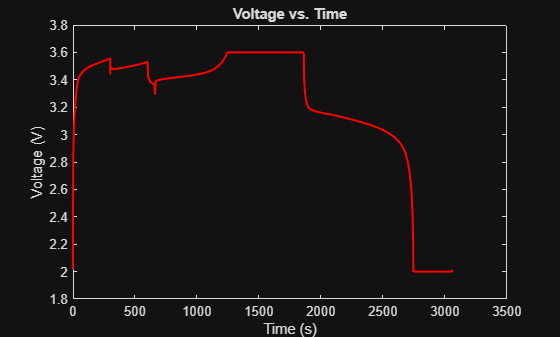

% downloads and loads data into the cycleData object
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
cycleData = data(data.Cycle_Index == 1, :);

% calculates time (final_time - initial_time)
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

% calculates power (P = I*V)
cycleData.Power = cycleData.Current.*cycleData.Voltage;

% plots Voltage vs. Time subplot
figure;
plot(cycleData.DateTime, cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");
title('Voltage vs. Time');

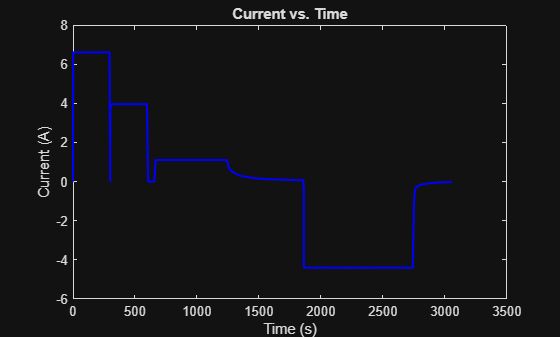


% plots Current vs. Time subplot
figure;
plot(cycleData.DateTime, cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');
xlabel("Time (s)");
title('Current vs. Time');

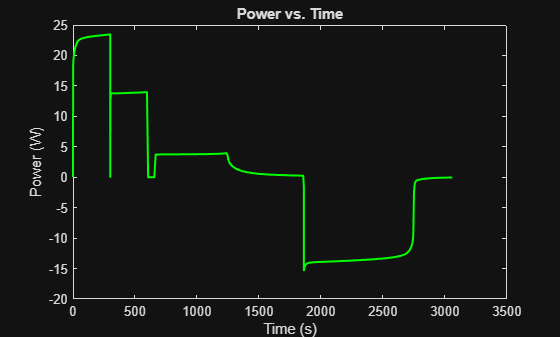


% plots Power vs. Time subplot
figure;
plot(cycleData.DateTime, cycleData.Power, '-g', 'LineWidth', 1.5);
ylabel('Power (W)');
xlabel('Time (s)');
title('Power vs. Time');

chargeData = cycleData(cycleData.Current > 0, :);

% time reset to 0 for charging period
t = chargeData.DateTime - chargeData.DateTime(1);
V = chargeData.Voltage;
I = chargeData.Current;
P = chargeData.Power;

%% fit the theoretical model
rcModel = fittype('3.6*(1-exp(-t./tau))', 'independent', 't', 'coefficients', 'tau');
[fitCurve, gof] = fit(t, V, rcModel, 'StartPoint', max(t)/3, 'Lower', eps);
tau = fitCurve.tau;

%% display fitting results in table
fitResults = table(tau, gof.rsquare, gof.rmse, 'VariableNames', {'Tau (s)','R^2','Root Mean Square Error (V)'});
disp(fitResults)

    Tau (s)      R^2      Root Mean Square Error (V)
    _______    _______    __________________________

    0.22793    0.22936             0.27328          



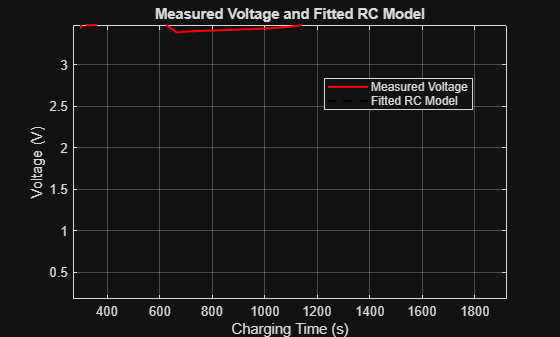


%% calculate smooth theoretical curve
tModel = linspace(min(t), max(t), 1000)';
VModel = fitCurve(tModel);

%% plot measured and theoretical voltage
figure;
plot(t, V, 'r-', tModel, VModel, 'k--', 'LineWidth', 1.5);

xlabel('Charging Time (s)');
ylabel('Voltage (V)');
title('Measured Voltage and Fitted RC Model');
legend('Measured Voltage','Fitted RC Model','Location','best');
grid on;

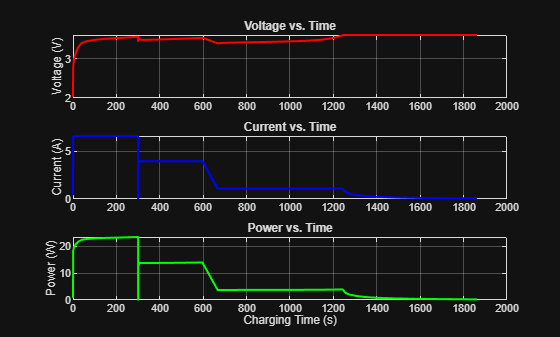


%% create subplots in one figure
figure;

subplot(3,1,1);
plot(t, V, 'r-', 'LineWidth', 1.5);
ylabel('Voltage (V)');
title('Voltage vs. Time');
grid on;

subplot(3,1,2);
plot(t, I, 'b-', 'LineWidth', 1.5);
ylabel('Current (A)');
title('Current vs. Time');
grid on;

subplot(3,1,3);
plot(t, P, 'g-', 'LineWidth', 1.5);
xlabel('Charging Time (s)');
ylabel('Power (W)');
title('Power vs. Time');
grid on;